# Calcalate generation features in 2019

The script is used to calculate generation features of the aggregated units in NYAM, such as max power,. min power, and max ramp rate.

## Import the RGGI generation data

clear;
% Import hourly generation data of generators in RGGI database in the 2019 whole year
genFileDir = "D:\EERL\ny_academic_model\data\EPA_AMPD\2019\";
genFileName = "emission*.csv";
generationDataStore = fileDatastore(genFileDir + genFileName, "ReadFcn", @importGenerationData, "UniformRead", true);
generationAll = readall(generationDataStore);

## Import RGGI to NYCA reference table

% Import the reference table from RGGI to NYISO NYCA database
RGGI2NYCA2019 = importRGGI2NYCA("D:\EERL\ny_academic_model\data\EPA_AMPD\RGGI_2_NYCA_2019.xlsx");
generatorCombiner = RGGI2NYCA2019(:, ["NYISOname", "PTID", "FacilityName", "FacilityID", "UnitID", "NYAMUnit", "Region", "UnitType", "FuelType"]);
% Exclude generators that are not included in NYAM units
generatorCombiner = generatorCombiner(generatorCombiner.NYAMUnit ~= 'NA',:);
% Exclude generators fueling on wood and refuse (renewable energy)
generatorCombiner = generatorCombiner(generatorCombiner.FuelType ~= "Wood" & generatorCombiner.FuelType ~= "Refuse", :);
% Remove unused categories
generatorCombiner.FuelType = removecats(generatorCombiner.FuelType);
generatorCombiner.NYAMUnit = removecats(generatorCombiner.NYAMUnit);

% Create arrays of key features
NYISONames = unique(generatorCombiner.NYISOname);
PTIDs = unique(generatorCombiner.PTID);
unitTypes = unique(generatorCombiner.UnitType);
fuelTypes = unique(generatorCombiner.FuelType);
NYAMUnits = unique(generatorCombiner.NYAMUnit);

## Group summary of nameplate capacity in NYCA database

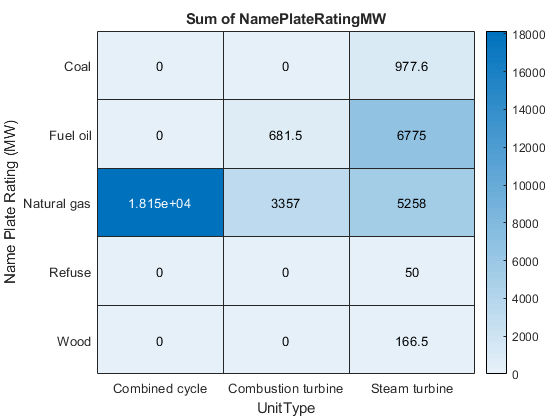

% Group summary of nameplate capacity by NYAM units
aggCapSummary = groupsummary(RGGI2NYCA2019, "NYAMUnit", ["mean", "sum"], "NamePlateRatingMW");
% Group summary of nameplate capacity by unit type and fuel type
unitFuelTypeCapSummary = groupsummary(RGGI2NYCA2019, ["UnitType", "FuelType"] , ["mean", "sum"], "NamePlateRatingMW");
% Heat map of nameplate capacity by unit type and fuel type
fHeatMap1 = figure(1);
heatmap(fHeatMap1, RGGI2NYCA2019, "UnitType", "FuelType", "ColorVariable", "NamePlateRatingMW", "ColorMethod","sum");
ylabel("Name Plate Rating (MW)");

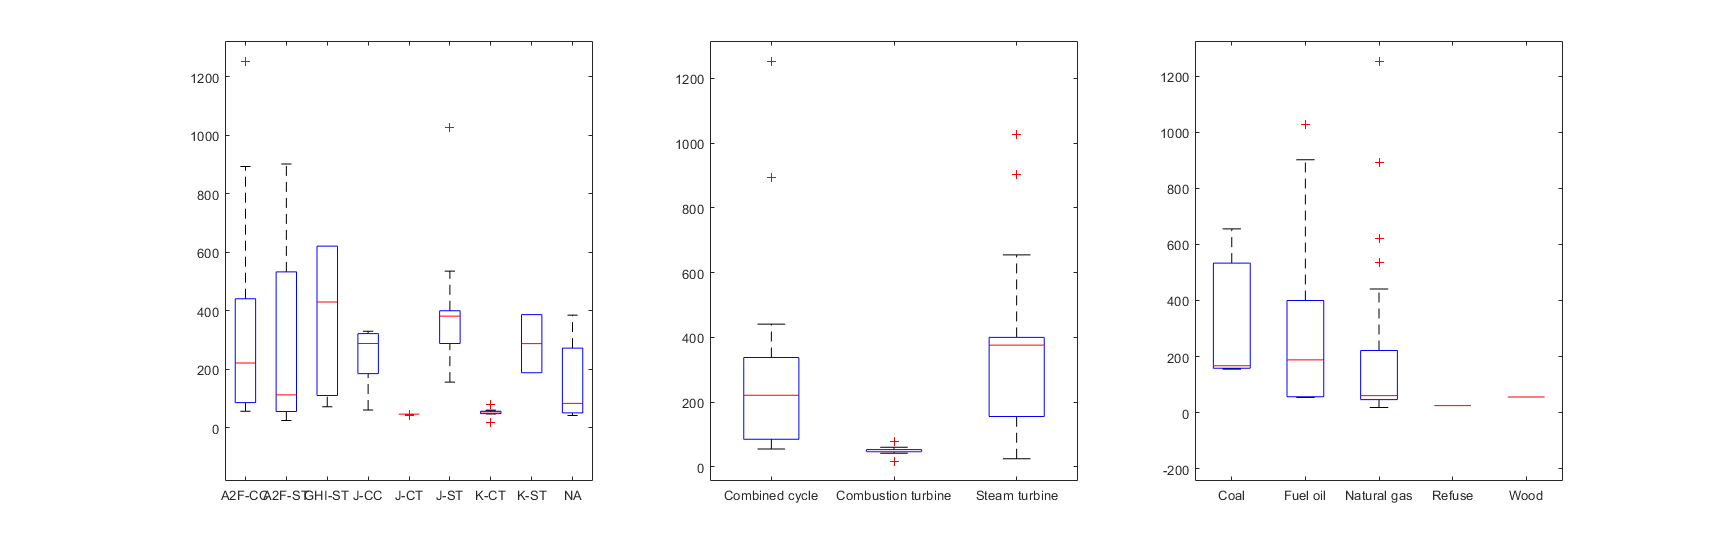

% Box plot of nameplate capacity grouped by units
fBox1 = figure(2);
set(fBox1, 'Unit', 'normalized','Position', [0.1, 0.1, 0.9, 0.5], 'Visible', 'off');
subplot(1,3,1);
boxplot(RGGI2NYCA2019.NamePlateRatingMW, RGGI2NYCA2019.NYAMUnit);
subplot(1,3,2);
boxplot(RGGI2NYCA2019.NamePlateRatingMW, RGGI2NYCA2019.UnitType);
subplot(1,3,3);
boxplot(RGGI2NYCA2019.NamePlateRatingMW, RGGI2NYCA2019.FuelType);
set(fBox1, 'visible', "on", 'color', 'w');

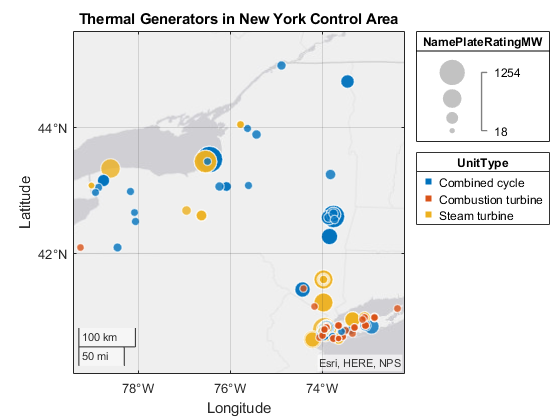

% Geobubble plot of generators grouped by unit type
fGeo1 = figure(3);
gb = geobubble(fGeo1, RGGI2NYCA2019, "FacilityLatitude", "FacilityLongitude", "ColorVariable", "UnitType", "SizeVariable", "NamePlateRatingMW");
% gb.Basemap = "topographic";
title("Thermal Generators in New York Control Area");

## Combine the generation table with the reference table

% Combine the RGGI database with the NYCA database
% Join tables
generationAllJoint = innerjoin(generationAll,generatorCombiner,'Keys',...
    {'FacilityName','FacilityID','UnitID'}, 'LeftVariables', {'FacilityName',...
    'FacilityID', 'UnitID', 'Date', 'Hour', 'GrossLoadMW', 'OperatingTime'})

generationAllJoint = 1454160×13 table
    FacilityName    FacilityID    UnitID       Date       Hour    GrossLoadMW    OperatingTime    NYISOname    PTID     NYAMUnit    Region         UnitType          FuelType  
    ____________    __________    ______    __________    ____    ___________    _____________    _________    _____    ________    ______    __________________    ___________

    23rd and 3rd       7910        2301     01/01/2019      0          0               0          Gowanus 5    24156      J-CT        J       Combustion turbine    Nat

## Subsetting generators by facility and calculate generation features

% Define arrays to record NYISO generators' parameter
maxPowerGen = zeros(size(NYISONames));
minPowerGen = zeros(size(NYISONames));
maxRampUpGen = zeros(size(NYISONames));
maxRampDownGen = zeros(size(NYISONames));

for i=1:length(NYISONames)
    genName = NYISONames(i);
    genSet = generationAllJoint(generationAllJoint.NYISOname == genName, :);
    [PMaxGen, PMinGen, RampUpMaxGen, RampDownMaxGen] = GenAggregator(genSet);
    maxPowerGen(i) = PMaxGen;
    minPowerGen(i) = PMinGen;
    maxRampUpGen(i) = RampUpMaxGen;
    maxRampDownGen(i) = RampDownMaxGen;
end

% Combine generator parameters into one summary table
maxRamp60Gen = (maxRampUpGen + abs(maxRampDownGen))/2;
maxRamp30Gen = maxRamp60Gen/2;
maxRamp10Gen = maxRamp30Gen/3;
maxRampAgcGen = maxRamp10Gen/10;
genSummary = table(NYISONames, maxPowerGen, minPowerGen, maxRampAgcGen);

% Add generator information to the generator summary table
genSummary = innerjoin(genSummary,generatorCombiner,'LeftKeys',...
    {'NYISONames'},'RightKeys',{'NYISOname'})

genSummary = 166×12 table
           NYISONames            maxPowerGen    minPowerGen    maxRampAgcGen     PTID            FacilityName           FacilityID    UnitID    NYAMUnit    Region         UnitType          FuelType  
    _________________________    ___________    ___________    _____________    ______    __________________________    __________    ______    ________    ______    __________________    ___________

    Allegany                          66             0            0.73333       23514     Allegany Station No. 133        10619       1          A2F-CC      A2F     

## Fit categorical linear regression model

### Linear regression model of maximum power generation

lmMaxPowerGen = fitlm(genSummary, 'maxPowerGen ~ UnitType * FuelType + Region','RobustOpts','on')

lmMaxPowerGen = Linear regression model (robust fit):
    maxPowerGen ~ 1 + Region + UnitType*FuelType

Estimated Coefficients:
                                                        Estimate      SE       tStat        pValue  
                                                        ________    ______    ________    __________

    (Intercept)                                          54.576     44.746      1.2197       0.22445
    Region_GHI                                             9.85     59.517      0.1655       0.86877
    Region_J                                             203.83     34.453      5.9162     2.058e-08
    Region_K                                             223.81     41.937      5.3369    3.3264e-07
    UnitType_Combustion turbine                     <

anovaMaxPowerGen = anova(lmMaxPowerGen, 'component')

anovaMaxPowerGen = 5×5 table
                           SumSq       DF       MeanSq        F         pValue  
                         __________    ___    __________    ______    __________

    Region                    69949      3         23316    1.6171       0.18759
    UnitType             1.8052e+06      2    9.0259e+05      62.6    1.0218e-20
    FuelType             2.9089e+05      1    2.9089e+05    20.175    1.3629e-05
    UnitType:FuelType    7.1145e+05      2    3.5573e+05    24.672    4.8171e-10
    Error                2.2637e+06    157         14418                        


### Linear regression model of maximum ramp rate

lmMaxRampAgcGen = fitlm(genSummary, 'maxRampAgcGen ~ UnitType * FuelType + Region','RobustOpts','on')

lmMaxRampAgcGen = Linear regression model (robust fit):
    maxRampAgcGen ~ 1 + Region + UnitType*FuelType

Estimated Coefficients:
                                                         Estimate       SE         tStat        pValue  
                                                        __________    _______    _________    __________

    (Intercept)                                            0.63233    0.42551       1.4861       0.13931
    Region_GHI                                             0.14339    0.56597      0.25334       0.80034
    Region_J                                                 2.119    0.32763       6.4677    1.2509e-09
    Region_K                                                2.2054     0.3988       5.5302    1.3401e-07
    UnitType_Combustion t

anova(lmMaxRampAgcGen, 'component')

ans = 5×5 table
                          SumSq     DF     MeanSq        F          pValue  
                         _______    ___    _______    ________    __________

    Region               0.38743      3    0.12914    0.099046       0.96044
    UnitType              116.96      2     58.478       44.85    3.9168e-16
    FuelType              10.347      1     10.347      7.9354     0.0054708
    UnitType:FuelType      32.94      2      16.47      12.632    8.1894e-06
    Error                 204.71    157     1.3039                          


### Subset the generator summary table by unit type, fuel type, and NYAM unit

% Subset the generator summary table by unit type
genSummaryCC = genSummary(genSummary.UnitType == "Combined cycle", :);
genSummaryCT = genSummary(genSummary.UnitType == "Combustion turbine", :);
genSummaryST = genSummary(genSummary.UnitType == "Steam turbine", :);
% Subset the generator summary table by fuel type
genSummaryNG = genSummary(genSummary.FuelType == "Natural gas", :);
genSummaryFO = genSummary(genSummary.FuelType == "Fuel oil", :);
genSummaryCO = genSummary(genSummary.FuelType == "Coal", :);
% Subset the generator summary table by NYAM units
genSummaryA2FCC = genSummary(genSummary.NYAMUnit == "A2F-CC", :);
genSummaryA2FST = genSummary(genSummary.NYAMUnit == "A2F-ST", :);
genSummaryGHIST = genSummary(genSummary.NYAMUnit == "GHI-ST", :);
genSummaryJCC = genSummary(genSummary.NYAMUnit == "J-CC", :);
genSummaryJCT = genSummary(genSummary.NYAMUnit == "J-CT", :);
genSummaryJST = genSummary(genSummary.NYAMUnit == "J-ST", :);
genSummaryKCT = genSummary(genSummary.NYAMUnit == "K-CT", :);
genSummaryKST = genSummary(genSummary.NYAMUnit == "K-ST", :);

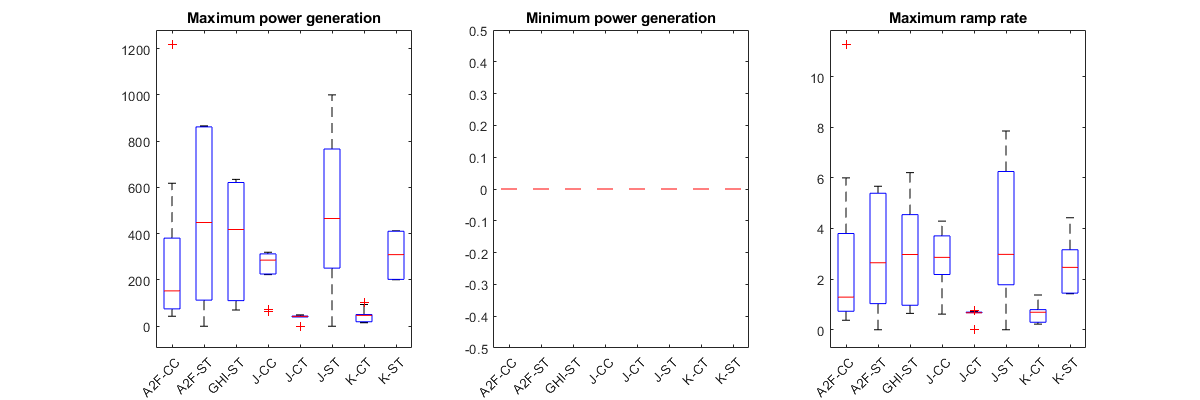

fBox2 = figure(4);
reset(fBox2);
set(fBox2, 'Units',"pixels", 'Position',[100, 100, 1200, 400], 'Visible', 'off');
subplot(1,3,1);
boxplot(genSummary.maxPowerGen, genSummary.NYAMUnit);
title("Maximum power generation");
xtickangle(45);
subplot(1,3,2);
boxplot(genSummary.minPowerGen, genSummary.NYAMUnit);
title("Minimum power generation");
xtickangle(45);
subplot(1,3,3);
boxplot(genSummary.maxRampAgcGen, genSummary.NYAMUnit);
title("Maximum ramp rate");
xtickangle(45);
set(fBox2, 'visible', 'on', 'color', 'w');

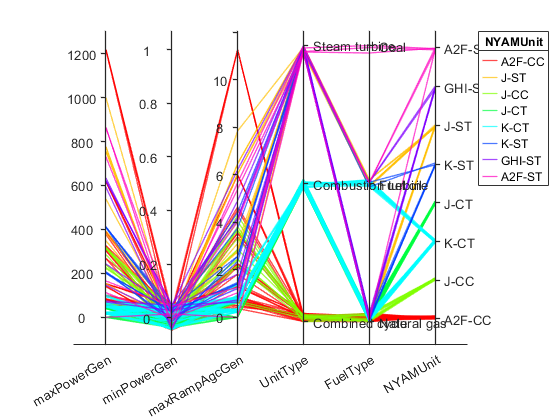

% Parallel coordinates plot
fParellel = figure(5);
coordvars = {'maxPowerGen', 'minPowerGen', 'maxRampAgcGen', 'UnitType', 'FuelType', 'NYAMUnit'};
p = parallelplot(genSummary, "CoordinateVariables", coordvars, 'GroupVariable', "NYAMUnit", 'DataNormalization', "range");
unitsOrder = {'A2F-CC', 'J-CC', 'K-CT', 'J-CT', 'K-ST', 'J-ST','GHI-ST', 'A2F-ST'};
categoricalUnits = categorical(genSummary.NYAMUnit, unitsOrder, 'Ordinal', true);
orderUnits = reordercats(categoricalUnits, unitsOrder);
p.SourceTable.NYAMUnit = orderUnits;
fuelsOrder = {'Natural gas', 'Fuel oil', 'Coal'};
categoricalFuelTypes = categorical(genSummary.FuelType, fuelsOrder, 'Ordinal', true);
orderFuelTypes = reordercats(categoricalFuelTypes, fuelsOrder);
p.SourceTable.FuelType = orderFuelTypes;
p.Color = hsv(8);

## Subsetting generators by NYAM Units and calculate generation features

% Loop through the NYAM units and get key features of the units
maxPowerAgg = zeros(size(NYAMUnits));
minPowerAgg = zeros(size(NYAMUnits));
maxRampUpAgg = zeros(size(NYAMUnits));
maxRampDownAgg= zeros(size(NYAMUnits));

for i=1:length(NYAMUnits)
    unitName = NYAMUnits(i);
    unitSet = generationAllJoint(generationAllJoint.NYAMUnit == unitName, :);
    [PMaxUnit, PMinUnit, RampUpMaxUnit, RampDownMaxUnit] = GenAggregator(unitSet);
    maxPowerAgg(i) = PMaxUnit;
    minPowerAgg(i) = PMinUnit;
    maxRampUpAgg(i) = RampUpMaxUnit;
    maxRampDownAgg(i) = RampDownMaxUnit;
end

maxRamp60Agg = (maxRampUpAgg + abs(maxRampDownAgg))./2;
maxRamp30Agg = maxRamp60Agg./2;
maxRamp10Agg = maxRamp60Agg./6;
maxRampAgcAgg = maxRamp60Agg./60;
aggSummary = table(NYAMUnits, maxPowerAgg, minPowerAgg, maxRampAgcAgg, maxRamp10Agg, maxRamp30Agg)

aggSummary = 8×6 table
    NYAMUnits    maxPowerAgg    minPowerAgg    maxRampAgcAgg    maxRamp10Agg    maxRamp30Agg
    _________    ___________    ___________    _____________    ____________    ____________

     A2F-CC         4161            108             17.4              174             522   
     A2F-ST         1633              0            6.425            64.25          192.75   
     GHI-ST         1189              0           6.5083           65.083          195.25   
     J-CC           2716            493           12.108           121.08          363.25   
     J-CT            882              0           7.8417           78.417          235.25   
     J-ST           3729              0           16.433           164.33             493   
     K-CT           1039    

aggSummary4NYAM = aggSummary([2, 2, 3, 6, 8, 1, 4, 5, 7], :)

aggSummary4NYAM = 9×6 table
    NYAMUnits    maxPowerAgg    minPowerAgg    maxRampAgcAgg    maxRamp10Agg    maxRamp30Agg
    _________    ___________    ___________    _____________    ____________    ____________

     A2F-ST         1633              0            6.425            64.25          192.75   
     A2F-ST         1633              0            6.425            64.25          192.75   
     GHI-ST         1189              0           6.5083           65.083          195.25   
     J-ST           3729              0           16.433           164.33             493   
     K-ST           2060             34           10.025           100.25          300.75   
     A2F-CC         4161            108             17.4              174             522   
     J-CC           271

### Compare the results with the data in Steve's thesis and Leah's report

maxPowerS = [5300; 2800; 2900; 3300; 2600; 3900; 2377; 2000];
minPowerS = [530; 420; 435; 330; 65; 585; 59.425; 390];
maxRampAgcS = [14.13; 3.12; 3.22; 8.8; 17.33; 4.33; 15.85; 2.89];
maxPowerL = [4517; 1882; 1831; 2147; 911; 4013; 1095; 2188];
minPowerL = [48; 1001; 733; 11; 539; 7; 303; 31];
maxRampAgcL = [20.06; 1.6; 1.48; 17.52; 1.43; 7.07; 1.86; 5.13];
genSummaryS = table(NYAMUnits, maxPowerS, minPowerS, maxRampAgcS);
genSummaryL = table(NYAMUnits, maxPowerL, minPowerL, maxRampAgcL);
genSummaryAll = join(aggSummary,genSummaryS,'Keys',{'NYAMUnits'}, 'LeftVariables', {'NYAMUnits', 'maxPowerAgg', 'minPowerAgg', 'maxRampAgcAgg'});
genSummaryAll = join(genSummaryAll, genSummaryL, 'Keys', {'NYAMUnits'})

genSummaryAll = 8×10 table
    NYAMUnits    maxPowerAgg    minPowerAgg    maxRampAgcAgg    maxPowerS    minPowerS    maxRampAgcS    maxPowerL    minPowerL    maxRampAgcL
    _________    ___________    ___________    _____________    _________    _________    ___________    _________    _________    ___________

     A2F-CC         4161            108             17.4          5300           530         14.13         4517           48          20.06   
     A2F-ST         1633              0            6.425          2800           420          3.12         1882         1001            1.6   
     GHI-ST         1189              0           6.5083    

fBar1 = figure(6);
bar(genSummaryAll.NYAMUnits, [genSummaryAll.maxPowerAgg, genSummaryAll.maxPowerL, genSummaryAll.maxPowerS]);
legend("2019-Bo", "2018-Leah", "2016-Steve");
xlabel("NYAM Units");
ylabel("Maximum Power Generation (MW)");
title("Maximum Power Generation of NYAM Untis");

fBar2 = figure(7);
bar(genSummaryAll.NYAMUnits, [genSummaryAll.minPowerAgg, genSummaryAll.minPowerL, genSummaryAll.minPowerS]);
legend("2019-Bo", "2018-Leah", "2016-Steve");
xlabel("NYAM Units");
ylabel("Minimum Power Generation (MW)");
title("Minimum Power Generation of NYAM Units");

fBar3 = figure(8);
bar(genSummaryAll.NYAMUnits, [genSummaryAll.maxRampAgcAgg, genSummaryAll.maxRampAgcL, genSummaryAll.maxRampAgcS]);
legend("2019-Bo", "2018-Leah", "2016-Steve");
xlabel("NYAM Units");
ylabel("Maximum Ramp Rate (MW/min)");
title("Maximum Ramp Rate of NYAM Units");